clc;
clear all;

%Definição dos parâmetros do Robô RR

### Posição de repouso do robô

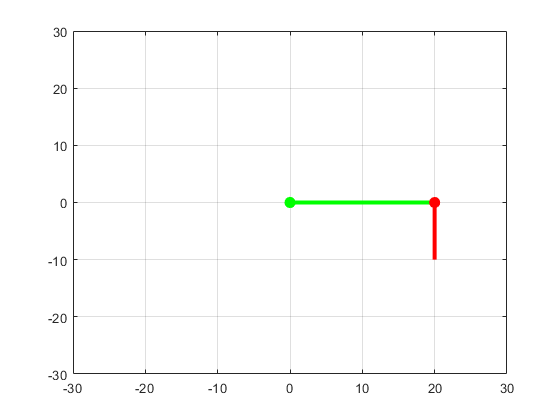

plot([0 20],[0 0], 'LineWidth', 3, 'Color', 'g');
xlim([-30 30])
ylim([-30 30])
hold on
plot([20 20],[0 -10], 'LineWidth', 3, 'Color', 'r');
sz = 70;
scatter(0,0,sz,'filled','green')
scatter(20,0,sz, 'filled','red')
grid on;
hold off

a1=20;
a2=10;
alfa=-pi/2;% parâmetro necessário para que a posição zero do robô tenha a configuração desejada na qual o eixo x2 (cotovelo)  está a -90º em relação a x1 (levantamento do braço)

%Espaço de Trabalho

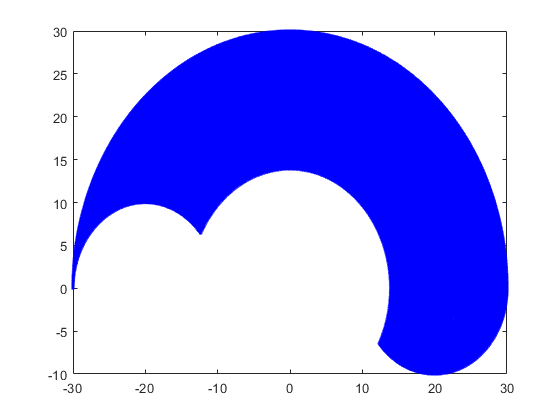

i=0;

theta1_limInf=0;%limite inferior de theta 1 em graus
theta1_limSup=180;%limite superior de theta 1 em graus
theta2_limInf=-50;%limite inferior de theta 2 em graus
theta2_limSup=90;%limite superior de theta 2 em graus

theta1_limInf=deg2rad(theta1_limInf);
theta1_limSup=deg2rad(theta1_limSup);
theta2_limInf=deg2rad(theta2_limInf);
theta2_limSup=deg2rad(theta2_limSup);


for theta1=theta1_limInf:(theta1_limSup-theta1_limInf)/199:theta1_limSup,
    for theta2=theta2_limInf:(theta2_limSup-theta2_limInf)/199:theta2_limSup,
        i=i+1;
        x(i)=a1*cos(theta1)+a2*cos(theta1+theta2+alfa);%cinemática direta de posição x
        y(i)=a1*sin(theta1)+a2*sin(theta1+theta2+alfa); %cinemática direta de posição y
     end
end
plot(x,y,'.b');
hold on;

%Definição da Trajetória Retilínea

%TRAJETORIA 1

% p0_r=[16.24, -6,219]
% p1_r=[24.74, 13.57];

% TRAJETORIA 2
p0_r=[2.603 13.67];%xi,yi
p1_r=[18.5 2.997];%xf,yf


Dx=p1_r(1)-p0_r(1); 
Dy=p1_r(2)-p0_r(2);
A=Dy/Dx;
b=p0_r(1,2)-A*p0_r(1,1);
k=0;
n_pontos_r=80;
for i=p0_r(1,1):(p1_r(1,1)-p0_r(1,1))/(n_pontos_r-1):p1_r(1,1),
    k=k+1;
    tx_r(k)=i;
    ty_r(k)=A*tx_r(k)+b ;
end


%Definição do Tempo da Trajetória Retilínea e do Intervalo de Amostragem

Tempo_r=30e-3; % Intervalo de amostragem igual a 40 milissegundos

T_r(1)=0;
for i=2:n_pontos_r,
    T_r(i)=T_r(i-1)+Tempo_r;
end

%Definição dos Intervalos de Tempo da Trajetória Retilínea

dT_r=diff(T_r);


K_r=[10,0;0,10];
format compact;
a1 = 20; %link 1 length
a2 = 10; %link 2 length

% ponto inicial trajetoria 1 
% xPos = 14.89;
% yPos = -2.393;

% ponto inicial trajetoria 2
xPos = 2.603;
yPos = 13.67;

P = [xPos yPos]; 

theta2 = - acos((xPos^2 + yPos^2 - a1^2 - a2^2)/(2*a1*a2));
theta1 = atan2(yPos,xPos) - atan2((a2*sin(theta2)),(a1 + a2*cos(theta2)));

theta2_d = rad2deg(theta2)

theta2_d = -139.9861

theta1_d = rad2deg(theta1)

theta1_d = 106.7385


alfa = -pi/2;

q_r(:,1) = [theta1;(theta2-alfa)];

Rotz1 = [cos(theta1) -sin(theta1) 0 0;...
          sin(theta1)  cos(theta1) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans1 = [1 0 0 a1;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];
Rotz2 = [cos(theta2) -sin(theta2) 0 0;...
          sin(theta2)  cos(theta2) 0 0;...
          0 0 1 0;...
          0 0 0 1];
Trans2 = [1 0 0 a2;...
           0 1 0 0;...
           0 0 1 0;...
           0 0 0 1];

T = Rotz1*Trans1*Rotz2*Trans2

T =     0.8363    0.5483         0    2.6030
   -0.5483    0.8363         0   13.6700
         0         0    1.0000         0
         0         0         0    1.0000


T_01 = Rotz1*Trans1

T_01 =    -0.2880   -0.9576         0   -5.7601
    0.9576   -0.2880         0   19.1526
         0         0    1.0000         0
         0         0         0    1.0000



T_02 = T_01*Rotz2*Trans2

T_02 =     0.8363    0.5483         0    2.6030
   -0.5483    0.8363         0   13.6700
         0         0    1.0000         0
         0         0         0    1.0000



P = [0;0;0;1];
P1 = T_01*P; P2 = T_02*P;
hold on;
%plot([0 P1(1) P2(1)],[0 P1(2) P2(2)], 'LineWidth', 3, 'Color', 'g');
plot([0 P1(1)],[0 P1(2)], 'LineWidth', 3, 'Color', 'g');
hold on
plot([P1(1) P2(1)],[P1(2) P2(2)], 'LineWidth', 3, 'Color', 'r');
sz = 70

sz = 70

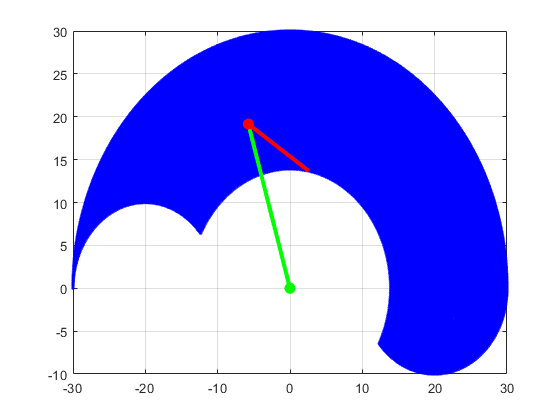

scatter(0,0,sz,'filled','green')
scatter(P1(1),P1(2),sz, 'filled','red')

grid on;

%Definição das velocidade desejadas do efetuador para trajetória Retilínea

dtx_r=diff(tx_r);
dty_r=diff(ty_r);

%CONTROLE DE TRAJETÓRIA RETILÍNEA

for i=1:n_pontos_r,
    X_pot_r(:,i)=[a1*cos(q_r(1,i))+a2*cos(q_r(1,i)+q_r(2,i)+alfa);
                a1*sin(q_r(1,i))+a2*sin(q_r(1,i)+q_r(2,i)+alfa)]; %posição corrente q_p do efetuador
            
    Xd_r(:,i)=[tx_r(i);
        ty_r(i)]; %posicao desejada (pd ou xd)
    
    e_r(:,i)=Xd_r(:,i)-X_pot_r(:,i); %erro de posição(e_p)
    
    if(i<n_pontos_r)
        
        %velocidade pd_ponto (feedfoward)
        dXd_r(:,i)=[dtx_r(i)./dT_r(:,i); dty_r(i)./dT_r(:,i)];
        
        %lei de controle u_p_barra - velocidade linear do efetuador relativo a contribuição da velocidade das juntas
        u_r(:,i)=K_r*e_r(:,i)+dXd_r(:,i);
        
        %velocidade das juntas qp_ponto=up -> inverso do jacobiano*lei de controle (u = (j(q_p)^-1*up)
        dq_r(:,i)=1/(a1*a2*sin(q_r(2,i)+alfa))*([a2*cos(q_r(1,i)+q_r(2,i)+alfa), a2*sin(q_r(1,i)+q_r(2,i)+alfa); -a1*cos(q_r(1,i))-a2*cos(q_r(1,i)+q_r(2,i)+alfa), -a1*sin(q_r(1,i))-a2*sin(q_r(1,i)+q_r(2,i)+alfa)])*u_r(:,i);
        
        %limitando a velocidade das juntas 60°/s%
         vel_lim_pos(:,i)=deg2rad(60);%em rad
         vel_lim_neg(:,i)=deg2rad(-60);%em rad
                
         if (dq_r(1,i) < vel_lim_neg(:,i))
             dq_r(1,i) = vel_lim_neg(:,i);
         end
         if (abs(dq_r(1,i)) > vel_lim_pos(:,i))
             dq_r(1,i) = vel_lim_pos(:,i);
         end
            
          if (dq_r(2,i) < vel_lim_neg(:,i))
             dq_r(2,i) = vel_lim_neg(:,i);
         end
         if (dq_r(2,i) > vel_lim_pos(:,i))
             dq_r(2,i) = vel_lim_pos(:,i);
         end
        
        %posição corrente q_p
        q_r(:,i+1)=q_r(:,i)+dq_r(:,i)*dT_r(:,i);
        
         
        
        %limites mecanicos
        if q_r(1,i+1)>theta1_limSup,%Limite Mecânico Medido
           q_r(1,i+1)=theta1_limSup;
        end
        if q_r(1,i+1)<theta1_limInf, %Limite Mecânico Medido
           q_r(1,i+1)=theta1_limInf;
        end
        if q_r(2,i+1)>theta2_limSup, %Limite Mecânico Medido
           q_r(2,i+1)=theta2_limSup;
        end
        if q_r(2,i+1)<theta2_limInf, %Limite Mecânico Medido
           q_r(2,i+1)=theta2_limInf;
        end
    end
end

%Gráfico da Trajetória Retilínea juntamente com Espaço de Trabalho

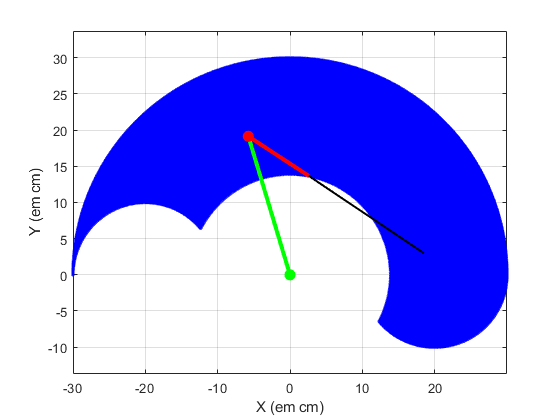

plot(tx_r,ty_r,'k', 'LineWidth', 1.5);
xlabel('X (em cm)'), ylabel('Y (em cm)');
axis equal;

% %Definição do Tempo da Trajetória e do Intervalo de Amostragem
% %%
% Tempo_c=30e-3; % Intervalo de amostragem igual a 70 milissegundos
% %k=0;
% %for i=0:Tempo_c/(n_pontos_c-1):Tempo_c,
% %    k=k+1;
% %    T_c(k)=i;
% %end
% T_c(1)=0;
% for i=2:n_pontos_c,
%     T_c(i)=T_c(i-1)+Tempo_c;
% end
%

%Conversão de Radianos para Graus

q_r=rad2deg(q_r); %Variáveis de Juntas para Trajetória Retilínea
dq_r=rad2deg(dq_r); %Velocidades das Juntas para Trajetória Retilínea

%Gráficos Pedidos

%********Trajetória Desejada X Trajetória Efetuada*************************

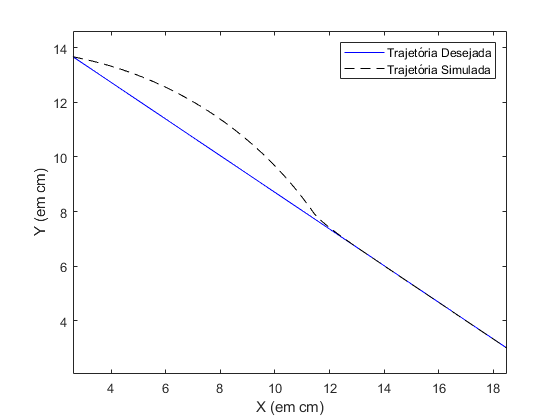

%Trajetória Retilínea
figure,
plot(tx_r,ty_r,'b',X_pot_r(1,:),X_pot_r(2,:),'k--');
ylabel('Y (em cm)'), xlabel('X (em cm)')%, title('Controle de Trajetória Retilínea do Efetuador');
legend('Trajetória Desejada','Trajetória Simulada');
axis equal

%********Posições Angulares das Juntas X Tempo*****************************

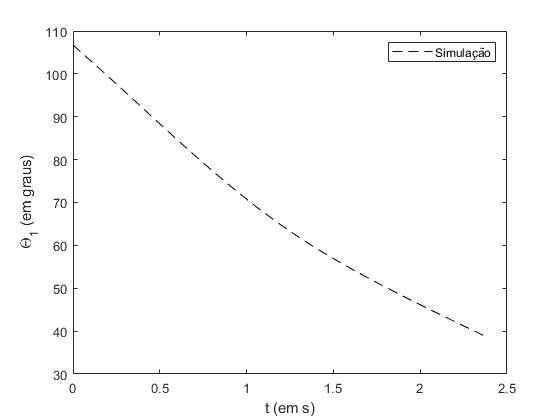

%Trajetória Retilínea
figure,
plot(T_r,q_r(1,:),'k--');
ylabel('\Theta_{1} (em graus)'), xlabel('t (em s)')%, title('Variação de Theta1 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

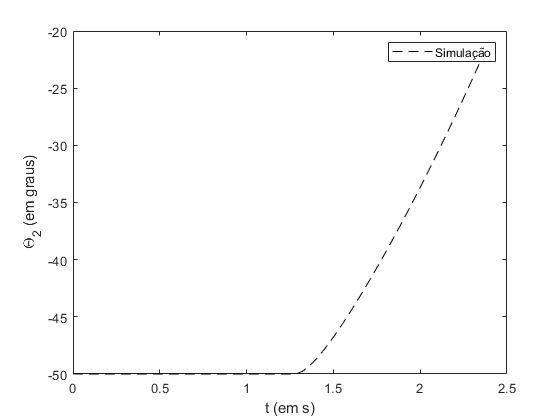

%axis equal;
figure,
plot(T_r,q_r(2,:),'k--');
ylabel('\Theta_{2} (em graus)'), xlabel('t (em s)')%, title('Variação de Theta2 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

%axis equal;

%********Erro de Posição X Tempo*******************************************

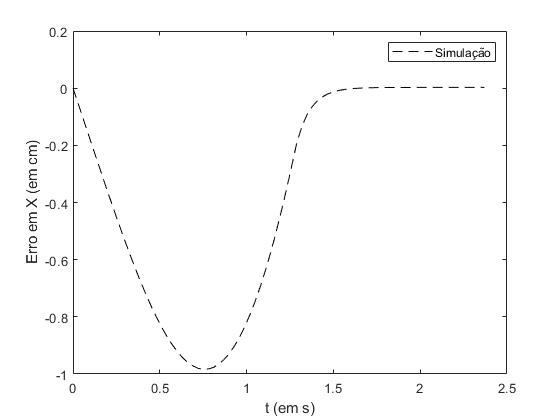

%Trajetória Retilínea
figure,
plot(T_r,e_r(1,:),'k--');
ylabel('Erro em X (em cm)'), xlabel('t (em s)')%, title('Variação do Erro em X ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

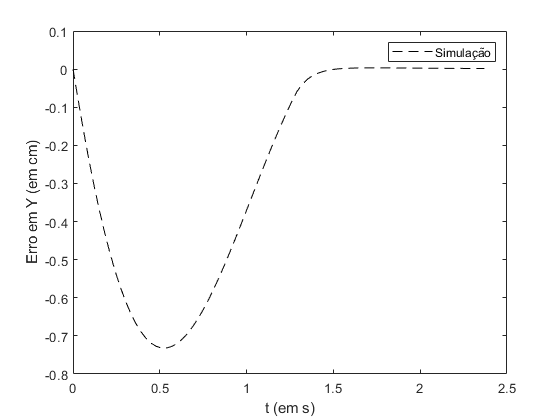


%axis equal;
figure,
plot(T_r,e_r(2,:),'k--');
ylabel('Erro em Y (em cm)'), xlabel('t (em s)')%, title('Variação de Erro em Y ao longo do tempo - Trajetória Retilínea');
legend('Simulação');


%axis equal;

%********Velocidade das Juntas X Tempo*******************************************

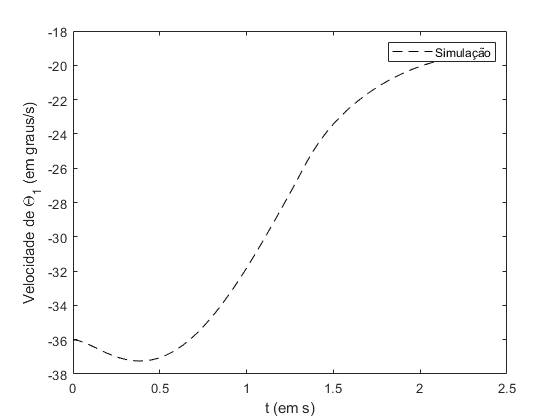

%Trajetória Retilínea
figure,
plot(T_r(1:n_pontos_r-1),dq_r(1,:),'k--');
ylabel('Velocidade de \Theta_{1} (em graus/s)'), xlabel('t (em s)')%, title('Variação da Velocidade da Junta 1 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

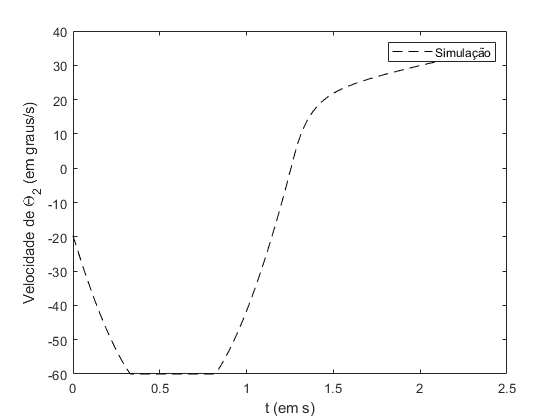

%axis equal;
figure,
plot(T_r(1:n_pontos_r-1),dq_r(2,:),'k--');
ylabel('Velocidade de \Theta_{2} (em graus/s)'), xlabel('t (em s)')%, title('Variação da Velocidade da Junta 2 ao longo do tempo - Trajetória Retilínea');
legend('Simulação');

%axis equal;